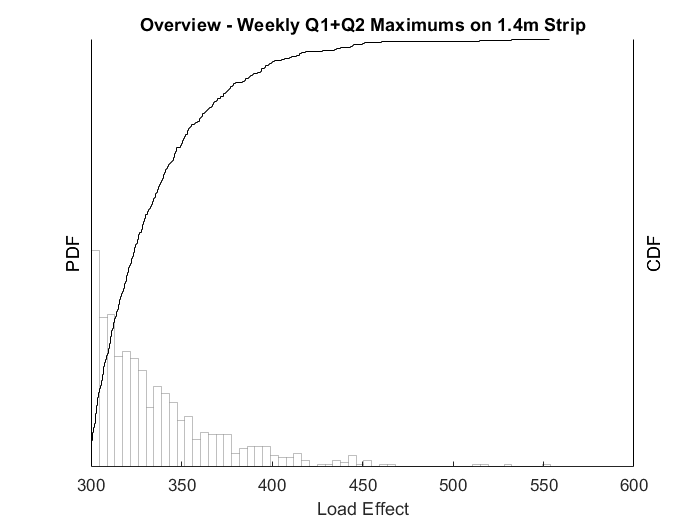

clear, clc
load('WIMWeeklyMaxQSum.mat')
Filter = "Class";
%hi
DMax = WeeklyMax.MaxLE(strcmp(WeeklyMax.ClassT,Filter));

% Plot the original data in histogram form along with matching normal curve
fOverview = figure('Name','Overview');
title('Overview - Weekly Q1+Q2 Maximums on 1.4m Strip')
xlabel('Load Effect'); ylabel('PDF')
set(gca,'YTick', [])
hold on
histogram(DMax,100,'EdgeAlpha',0.25,'FaceColor','none','normalization','pdf')
% Reset x axis limits
xlim([100 600])

% Calculate cut-off index, COi and cut-off value, COv
TailP = 0.20;
COi = round(length(DMax)*(1-TailP));
DMaxRank = sort(DMax);
COv = DMaxRank(COi);

% U = unique(DMax)
% histogram(U,100,'normalization','pdf')

% Emperical cdf (Ecdf) is a function that ranks data points in a sample (DMaxR) and gives
% the probability of non-exceedance (DMaxCDF)... it plots when given no variable 
[DMaxECDF, DMaxECDFRank] = ecdf(DMax); DMaxECDFRank = DMaxECDFRank';
% Plot the CDF on the same plot, but with a new y-axis
yyaxis right
% Use stairs to introduce stepped shape which is mathematically correct
stairs(DMaxECDFRank,DMaxECDF,'k')
ylabel('CDF')
set(gca,'YTick',[],'YColor','k')

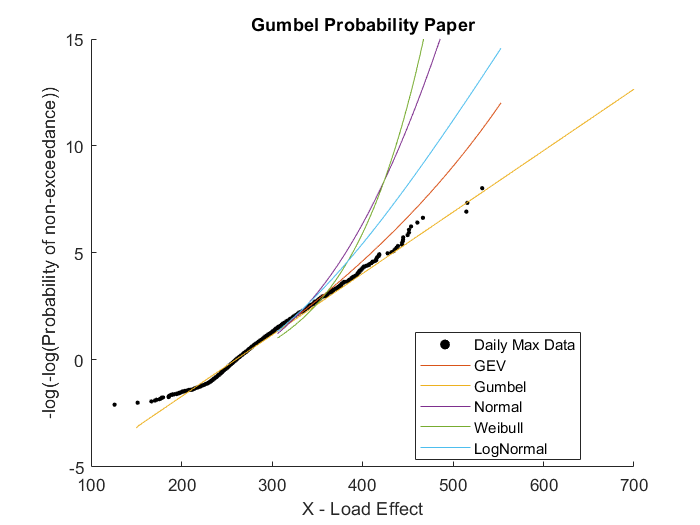


% The paper by EJOBrien uses Gumbel probability paper
% The Gumbel probability paper involves taking the -log(-log(CDF))
% Plot the original data (scatter)
fGumbelPP = figure('Name','Probability Paper');
hold on
scatter(DMaxECDFRank,-log(-log(DMaxECDF)),7,'k','filled','DisplayName','Daily Max Data');
xlabel('X - Load Effect'); ylabel('-log(-log(Probability of non-exceedance))')
title('Gumbel Probability Paper')
legend('location','best')
xMaxes = 150:700;
ylim([-5 15]); 

FitType = 'GeneralizedExtremeValue';
GEVp = LeastMeanSquaresFit(DMax,FitType,TailP);
GEVcdf = cdf(FitType,xMaxes,GEVp(1),GEVp(2),GEVp(3));
GEVpdf = pdf(FitType,xMaxes,GEVp(1),GEVp(2),GEVp(3));

% FitType = 'ExtremeValue';
% EVp = LeastMeanSquaresFit(DMax,FitType,TailP);
% EVcdf = cdf(FitType,xMaxes,EVp(1),EVp(2));
% EVpdf = pdf(FitType,xMaxes,EVp(1),EVp(2));

FitType = 'Weibull';
WEIp= LeastMeanSquaresFit(DMax,FitType,TailP);
WEIcdf = cdf(FitType,xMaxes,WEIp(1),WEIp(2));
WEIpdf = pdf(FitType,xMaxes,WEIp(1),WEIp(2));

FitType = 'Normal';
NORMp = LeastMeanSquaresFit(DMax,FitType,TailP);
NORMcdf = cdf(FitType,xMaxes,NORMp(1),NORMp(2));
NORMpdf = pdf(FitType,xMaxes,NORMp(1),NORMp(2));

FitType = 'Lognormal';
LOGNORMp = LeastMeanSquaresFit(DMax,FitType,TailP);
LOGNORMcdf = cdf(FitType,xMaxes,LOGNORMp(1),LOGNORMp(2));
LOGNORMpdf = pdf(FitType,xMaxes,LOGNORMp(1),LOGNORMp(2));

% Right now the extremevalue is fit to the whole of the data, not just the tail
FitType = 'ExtremeValue';
EVparam = evfit(-DMax);
EVcdfx = evcdf(-xMaxes,EVparam(1),EVparam(2));
EVpdf = evpdf(-xMaxes,EVparam(1),EVparam(2));
EVcdf = cumsum(EVpdf);

%h2 = qqplot(DMax,makedist('ExtremeValue'));

figure(fGumbelPP)
GEVLine = plot(xMaxes(xMaxes > COv & xMaxes < max(DMax)),-log(-log(GEVcdf(xMaxes > COv & xMaxes < max(DMax)))),'DisplayName','GEV');
EVLine = plot(xMaxes,-log(-log(EVcdf)),'DisplayName','Gumbel');
NormalLine = plot(xMaxes(xMaxes > COv & xMaxes < max(DMax)),-log(-log(NORMcdf(xMaxes > COv & xMaxes < max(DMax)))),'DisplayName','Normal');
WeibullLine = plot(xMaxes(xMaxes > COv & xMaxes < max(DMax)),-log(-log(WEIcdf(xMaxes > COv & xMaxes < max(DMax)))),'DisplayName','Weibull');
LogNormalLine = plot(xMaxes(xMaxes > COv & xMaxes < max(DMax)),-log(-log(LOGNORMcdf(xMaxes > COv & xMaxes < max(DMax)))),'DisplayName','LogNormal');

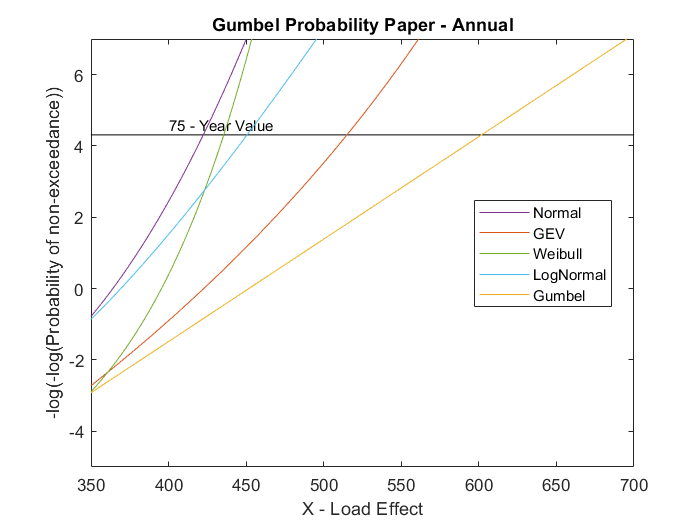


% Convert to annual by raising to the power of 250
AnnualProbPaper = figure('Name','Annual Max CDFs');
% Calculate 75-year return period and plo
SF = 1-(1/75);
plot([0 1000],[-log(-log(SF)) -log(-log(SF))],'k-','HandleVisibility',"off")
hold on
% Label particulars
xlabel('X - Load Effect'); ylabel('-log(-log(Probability of non-exceedance))')
title('Gumbel Probability Paper - Annual')
text(400,4.6,'75 - Year Value','FontSize',9,'Color','k')
legend('location','best')
xlim([350 700]); ylim([-5 7])
box on

% Convert to annual by raising to the power of 250
DMaxECDFa = DMaxECDF.^50;
NORMcdfa = NORMcdf.^50;
LOGNORMcdfa = LOGNORMcdf.^50;
GEVcdfa = GEVcdf.^250;
EVcdfa = EVcdf.^250;
WEIcdfa = WEIcdf.^250;

% plot annual CDFs from different distributions
plot(xMaxes,-log(-log(NORMcdfa)),'Color',NormalLine.Color,'DisplayName','Normal')
plot(xMaxes,-log(-log(GEVcdfa)),'Color',GEVLine.Color,'DisplayName','GEV')
plot(xMaxes,-log(-log(WEIcdfa)),'Color',WeibullLine.Color,'DisplayName','Weibull')
plot(xMaxes,-log(-log(LOGNORMcdfa)),'Color',LogNormalLine.Color,'DisplayName','LogNormal')
plot(xMaxes,-log(-log(EVcdfa)),'Color',EVLine.Color,'DisplayName','Gumbel')

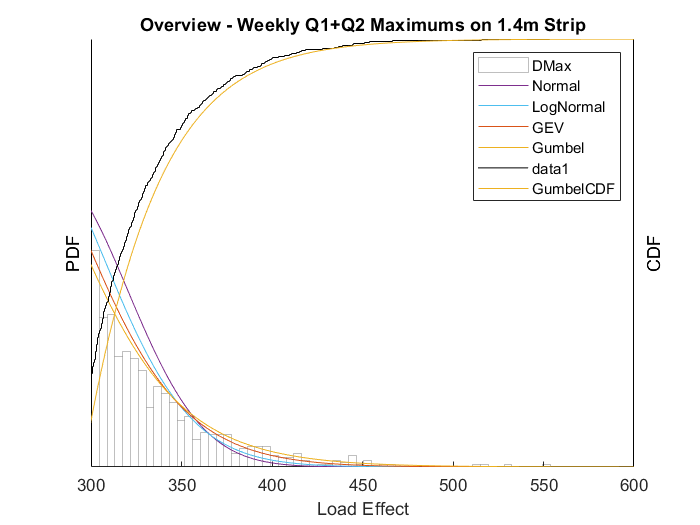


% Plot Exact Distribution
%plot(xMaxes,-log(-log(DMaxECDFa)),'k-','DisplayName','Emperical')


% Calculate Exact75 Year Characteristic Value
%[~,closestIndex] = min(abs(SF-DMaxCDFa));
%Exact75 = xParent(closestIndex);
% Calculate 75 Year Characteristic Value for the others
[~,closestIndex] = min(abs(SF-GEVcdfa));
GEV75 = xMaxes(closestIndex);
[~,closestIndex] = min(abs(SF-NORMcdfa));
NORM75 = xMaxes(closestIndex);

figure(fOverview)
hold on
yyaxis left
plot(xMaxes,NORMpdf,'-','Color',NormalLine.Color,'DisplayName','Normal')
plot(xMaxes,LOGNORMpdf,'-','Color',LogNormalLine.Color,'DisplayName','LogNormal')
plot(xMaxes,GEVpdf,'-','Color',GEVLine.Color,'DisplayName','GEV')
plot(xMaxes,EVpdf,'-','Color',EVLine.Color,'DisplayName','Gumbel')
legend
hold on
yyaxis right
% It really works when u do cumsum(pdf)
plot(xMaxes,EVcdf,'-','Color',EVLine.Color,'DisplayName','GumbelCDF')